function SARIMA_A514 = model_A5(A5)
    A51 = A5(:,1);
    SARIMA_A514 = arima('Constant',NaN,'ARLags',1:2,'D',0,'MALags',[1,2],'SARLags',[21,42],'Seasonality',21,'SMALags',[21,42],'Distribution','Gaussian');
    %SARIMA_A514 = arima('Constant',NaN,'ARLags',1:2,'D',0,'MALags',1:2,'SARLags',[147,294],'Seasonality',147,'SMALags',[147,294],'Distribution','Gaussian');
    SARIMA_A514 = estimate(SARIMA_A514,A51,'Display','off');
end

function SARIMA_D4 = model_D4(D4)
    D41 = D4(:,1);
    SARIMA_D4 = arima('Constant',NaN,'ARLags',1,'D',0,'MALags',[],'SARLags',42,'Seasonality',42,'SMALags',[],'Distribution','Gaussian');
    SARIMA_D4 = estimate(SARIMA_D4,D41,'Display','off');
end

function SARIMA_D317 = model_D3(D3)
    D31 = D3(:,1);
    SARIMA_D317 = arima('Constant',NaN,'ARLags',1,'D',0,'MALags',[],'SARLags',42,'Seasonality',42,'SMALags',[],'Distribution','Gaussian');
    SARIMA_D317 = estimate(SARIMA_D317,D31,'Display','off');
end

function SARIMA_D21 = model_D2(D2)
    D21 = D2(:,1);
    SARIMA_D21 = arima('Constant',NaN,'ARLags',1,'D',0,'MALags',[],'SARLags',42,'Seasonality',42,'SMALags',[],'Distribution','Gaussian');
    SARIMA_D21 = estimate(SARIMA_D21,D21,'Display','off');
end

function SARIMA_D1 = model_D1(D1)
    D11 = D1(:,1);
    %SARIMA_D1 = arima('Constant',NaN,'ARLags',1,'D',0,'MALags',[]);
    %SARIMA_D1 = arima('Constant',NaN,'ARLags',[],'D',0,'MALags',1);
    SARIMA_D1 = arima('Constant',NaN,'ARLags',1,'D',0,'MALags',[],'SARLags',21,'Seasonality',21,'SMALags',[],'Distribution','Gaussian');
    SARIMA_D1 = estimate(SARIMA_D1,D11,'Display','off');
end

function D_pred = forecast_narnet(D_train, forecast_horizon, feedbackDelays, hiddenLayerSize)
    % Ta funkcja trenuje sieć NAR i generuje prognozę o zadanym horyzoncie.
    %
    % D_train: wektor kolumnowy danych treningowych (np. D1, D2...)
    % forecast_horizon: liczba kroków do przodu (np. forecast_horizont/2)
    % feedbackDelays: wektor opóźnień (np. 1:2)
    % hiddenLayerSize: liczba neuronów w warstwie ukrytej (np. [10])

    % 1. Przygotuj dane dla sieci (musi być wektor wierszowy w komórce)
    D_train_cell = num2cell(D_train(:)');

    % 2. Zdefiniuj sieć NAR
    net = narnet(feedbackDelays, hiddenLayerSize);
    
    % 3. Wyłącz okno GUI treningu
    net.trainParam.showWindow = false;
    net.trainParam.showCommandLine = false;
    
    % 4. Przygotuj dane treningowe (format 'preparets')
    % Dla narnet, wejścia (X) są puste, a cele (T) to dane.
    % preparets automatycznie tworzy wejścia Xs z celów Ts.
    [Xs, Xi, Ai, Ts] = preparets(net, {}, {}, D_train_cell);

    % 5. Trenuj sieć
    [net_trained, tr] = train(net, Xs, Ts, Xi, Ai);
    
    % 6. Pobierz stany końcowe (final states) po treningu
    % Symulujemy sieć otwartą na danych treningowych, aby uzyskać
    % stany Xf (wejściowe) i Af (warstw) na końcu danych.
    [~, Xf, Af] = net_trained(Xs, Xi, Ai); 

    % 7. Zamknij pętlę (przełącz sieć w tryb prognozowania)
    net_closed = closeloop(net_trained);

    % 8. Przygotuj stany dla sieci zamkniętej
    % W sieci zamkniętej, stany wejściowe (Xf) stają się częścią
    % stanów warstw (Ai). Łączymy je.
    Ai_closed = [Af; Xf];
    Xi_closed = {}; % Sieć zamknięta nie ma wejść, więc jej stan wejściowy jest pusty.

    % 9. Wygeneruj prognozę używając jawnego wywołania 'sim'
    % Przekazujemy X (puste wejścia), Xi (puste stany wejściowe) i Ai (połączone stany warstw).
    [D_pred_cell, ~, ~] = sim(net_closed, cell(1, forecast_horizon), Xi_closed, Ai_closed);
    
    % 10. Konwertuj wynik z komórki z powrotem do wektora kolumnowego
    D_pred = cell2mat(D_pred_cell)';
end

% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);


$$$R^2_{\text{classic}} = 1 - \frac{\sum_i (y_i - \hat{y}_i)^2}{\sum_i (y_i - \bar{y})^2}$$$



$$$R^2_{\text{alt}} = \frac{\sum_{i=1}^{n} (\hat{y}_i - \bar{y})^2}{\sum_{i=1}^{n} (y_i - \bar{y})^2}$.

$$


function trainedNet_D1 = model_D1_lstm(D1_hist)
    % --- Hiperparametry dla D1 (Najbardziej chaotyczny) ---
    % Potrzebuje najwięcej pamięci i mocy
    lookback = 50;      
    hiddenUnits = 120;   
    maxEpochs = 10;

    % 1. Przygotowanie danych (X/Y)
    data = D1_hist(:);
    numSamples = length(data);
    X_train = cell(numSamples - lookback, 1);
    Y_train = zeros(numSamples - lookback, 1);
    for i = 1:(numSamples - lookback)
        X_train{i} = data(i : i + lookback - 1)'; 
        Y_train(i) = data(i + lookback);
    end

    % 2. Definicja Architektury
    layers = [ ...
        sequenceInputLayer(1, 'Name', 'input')
        lstmLayer(hiddenUnits, 'Name', 'lstm', 'OutputMode', 'last')
        fullyConnectedLayer(1, 'Name', 'fc')
        regressionLayer('Name', 'output')
    ];

    % 3. Opcje Treningu
    options = trainingOptions('adam', ...
        'MaxEpochs', maxEpochs, ...
        'MiniBatchSize', 32, ...
        'InitialLearnRate', 0.01, ...
        'Shuffle', 'every-epoch', ...
        'Verbose', 0, ...
        'Plots', 'none');

    % 4. Trening
    trainedNet_D1 = trainNetwork(X_train, Y_train, layers, options);
end


function pred = predict_lstm(net, history, steps, lookback)
    % net:       wytrenowany model (np. trainedNet_D1)
    % history:   pełna historia danych (np. D1_hist)
    % steps:     ile kroków w przód prognozować (np. 16)
    % lookback:  liczba kroków 'lookback' UŻYTA DO TRENINGU
    
    pred = zeros(steps, 1);
    history = history(:)'; % Upewnij się, że to wektor wierszowy
    
    % Pobierz ostatnie 'lookback' próbek z historii jako punkt startowy
    current_window = history(end - lookback + 1 : end);

    for i = 1:steps
        % 1. Prognozuj następny krok
        next_pred = predict(net, current_window);
        
        % 2. Zapisz prognozę
        pred(i) = next_pred;
        
        % 3. Zaktualizuj okno (usuń pierwszy, dodaj nowy na koniec)
        current_window = [current_window(2:end), next_pred];
    end
end

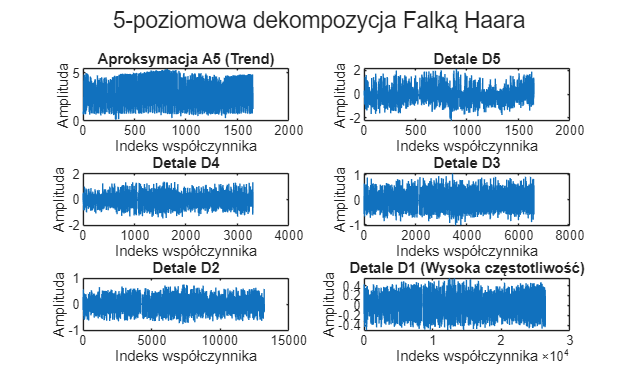

% ZBIÓR TRENINGOWY
[c, l] = wavedec(ab_diff_train_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji (niskie częstotliwości)
A1 = appcoef(c,l,'haar',1);
A2 = appcoef(c,l,'haar',2);
A3 = appcoef(c,l,'haar',3);
A4 = appcoef(c,l,'haar',4);
A5 = appcoef(c, l, 'haar', 5);

% Pobierz współczynniki detali (wysokie częstotliwości)
D5 = detcoef(c, l, 5);
D4 = detcoef(c, l, 4);
D3 = detcoef(c, l, 3);
D2 = detcoef(c, l, 2);
D1 = detcoef(c, l, 1);

% 2. RYSOWANIE WYKRESÓW
figure;

% Układ 3x2:
% [A5 | D5]
% [D4 | D3]
% [D2 | D1]

% --- Trend (Aproksymacja) ---
subplot(3, 2, 1);
plot(A5);
title('Aproksymacja A5 (Trend)');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

% --- Detale D5 (Najniższa częstotliwość detali) ---
subplot(3, 2, 2);
plot(D5);
title('Detale D5');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

% --- Detale D4 ---
subplot(3, 2, 3);
plot(D4);
title('Detale D4');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

% --- Detale D3 ---
subplot(3, 2, 4);
plot(D3);
title('Detale D3');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

% --- Detale D2 ---
subplot(3, 2, 5);
plot(D2);
title('Detale D2');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

% --- Detale D1 (Najwyższa częstotliwość / Szum) ---
subplot(3, 2, 6);
plot(D1);
title('Detale D1 (Wysoka częstotliwość)');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

% Poprawia czytelność całego okna
sgtitle('5-poziomowa dekompozycja Falką Haara');


% TEST
[c_test, l_test] = wavedec(ab_diff_test_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji
A5_test = appcoef(c_test, l_test, 'haar', 5);

% Pobierz współczynniki detali
D5_test = detcoef(c_test, l_test, 5);
D4_test = detcoef(c_test, l_test, 4);
D3_test = detcoef(c_test, l_test, 3);
D2_test = detcoef(c_test, l_test, 2);
D1_test = detcoef(c_test, l_test, 1);

forecast_horizont = 32 * 542;

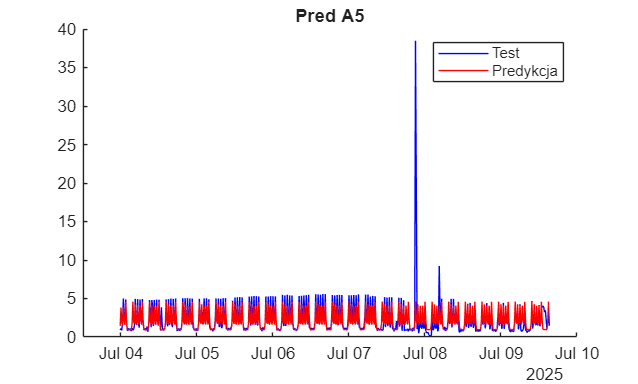

Mdl_D5 = model_A5(A5);
A5_pred = forecast(Mdl_D5, forecast_horizont/32, 'Y0', A5);

% 5. Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:length(A5_test)), A5_test, 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:length(A5_pred)), A5_pred, 'Color','red','DisplayName','Predykcja');
title('Pred A5');
legend;

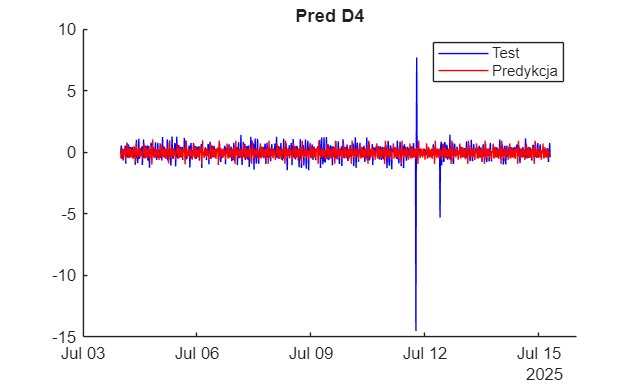

Mdl_D4 = model_D4(D4);
D4_pred = forecast(Mdl_D4, forecast_horizont/16, 'Y0', D4);

figure;
hold on;
plot(ab_diff_test.Time(1:length(D4_test)), D4_test, 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:length(D4_pred)), D4_pred, 'Color','red','DisplayName','Predykcja');
title('Pred D4');
legend;

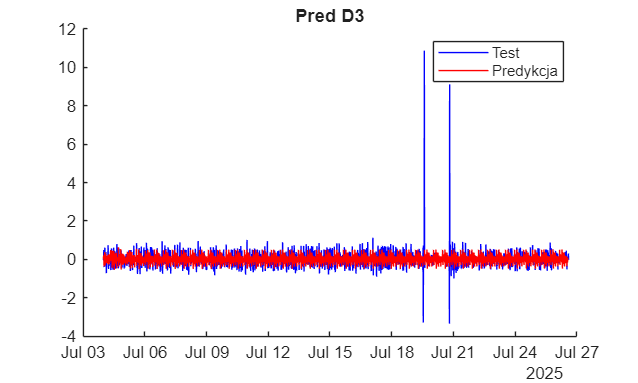


Mdl_D3 = model_D3(D3);
D3_pred = forecast(Mdl_D3, forecast_horizont/8, 'Y0', D3);

figure;
hold on;
plot(ab_diff_test.Time(1:length(D3_test)), D3_test, 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:length(D3_pred)), D3_pred, 'Color','red','DisplayName','Predykcja');
title('Pred D3');
legend;

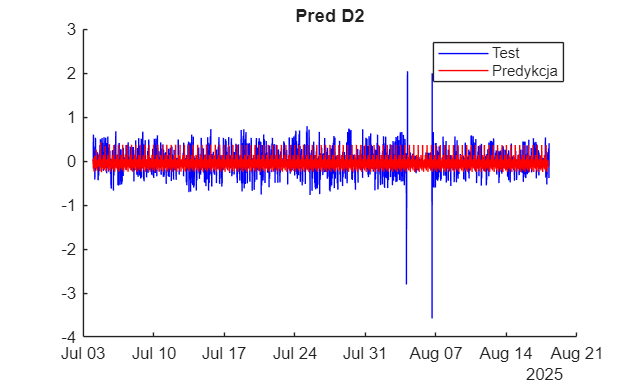


Mdl_D2 = model_D2(D2);
D2_pred = forecast(Mdl_D2, forecast_horizont/4, 'Y0', D2);

figure;
hold on;
plot(ab_diff_test.Time(1:length(D2_test)), D2_test, 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:length(D2_pred)), D2_pred, 'Color','red','DisplayName','Predykcja');
title('Pred D2');
legend;

Mdl_D1 = model_D1(D1)

Mdl_D1 =   arima with properties:

     Description: "ARIMA(1,0,0) Model Seasonally Integrated with Seasonal AR(21) (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 43
               D: 0
               Q: 0
        Constant: -2.41564e-05
              AR: {-0.251095} at lag [1]
             SAR: {-0.480518} at lag [21]
              MA: {}
             SMA: {}
     Seasonality: 21
            Beta: [1×0]
        Variance: 0.00876188

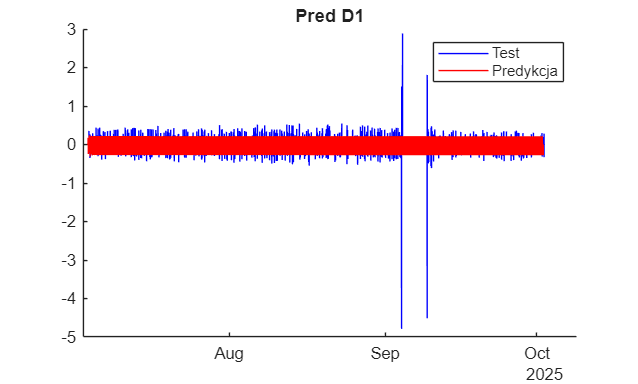

D1_pred = forecast(Mdl_D1, forecast_horizont/2, 'Y0', D1);

figure;
hold on;
plot(ab_diff_test.Time(1:length(D1_test)), D1_test, 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:length(D1_pred)), D1_pred, 'Color','red','DisplayName','Predykcja');
title('Pred D1');
legend;

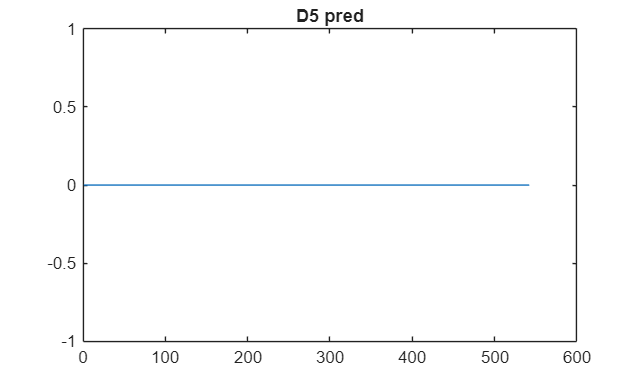


% D5
D5_pred = zeros(forecast_horizont/32, 1);
figure;
plot(D5_pred);
title('D5 pred');

%D5_pred = zeros(1,length(D5_pred))'; % zerowanie predykcji D5
c_pred_5 = [A5_pred', D5_pred'];
l_pred_5 = [length(A5_pred), length(D5_pred), length(A5_pred) + length(D5_pred)];
pred_5 = waverec(c_pred_5, l_pred_5, 'haar');

%D4_pred = zeros(1,length(D4_pred))'; % zerowanie predykcji D4
c_pred_4 = [pred_5, D4_pred'];
l_pred_4 = [length(pred_5), length(D4_pred), length(pred_5) + length(D4_pred)];
pred_4 = waverec(c_pred_4, l_pred_4, 'haar');

%D3_pred = zeros(1,length(D3_pred))'; % zerowanie predykcji D3
c_pred_3 = [pred_4, D3_pred'];
l_pred_3 = [length(pred_4), length(D3_pred), length(pred_4) + length(D3_pred)];
pred_3 = waverec(c_pred_3, l_pred_3, 'haar');

%D2_pred = zeros(1,length(D2_pred))'; % zerowanie predykcji D2
c_pred_2 = [pred_3, D2_pred'];
l_pred_2 = [length(pred_3), length(D2_pred), length(pred_3) + length(D2_pred)];
pred_2 = waverec(c_pred_2, l_pred_2, 'haar');

%D1_pred = zeros(1,length(D1_pred))'; % zerowanie predykcji D1
c_pred_1 = [pred_2, D1_pred'];
l_pred_1 = [length(pred_2), length(D1_pred), length(pred_2) + length(D1_pred)];
pred_1 = waverec(c_pred_1, l_pred_1, 'haar');

%{
c_pred_1 = [A1_pred', D1_pred'];
l_pred_1 = [length(A1_pred), length(D1_pred'), length(A1_pred) + length(D1_pred')];
pred_1 = waverec(c_pred_1, l_pred_1, 'haar');
%}

pred_full = pred_1;

y_test = ab_diff_test_norm(1:length(pred_full))';

mae_score_1 = mae(y_test, pred_full)

mae_score_1 = 0.2462

mape_score_1 = mape(y_test, pred_full)

mape_score_1 = 168.5299

rmse_score_1 = rmse(y_test, pred_full)

rmse_score_1 = 0.4829

r2_classic_1 = R2_classic(y_test, pred_full)

r2_classic_1 = 0.1724

r2_alt_1 = R2_alt(y_test, pred_full)

r2_alt_1 = 0.2551

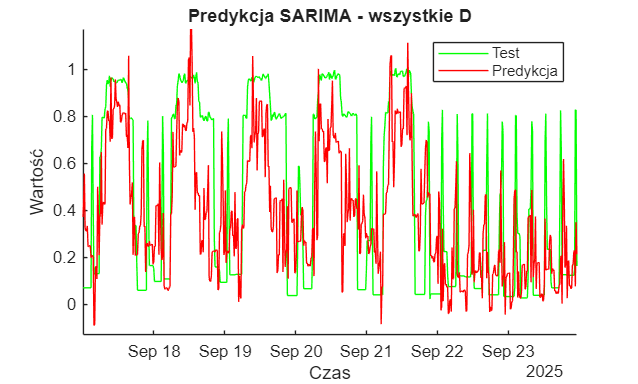


figure;
hold on;
%plot(ab_diff_train.Time, ab_diff_train_norm, 'Color','blue','DisplayName','Trening');
plot(ab_diff_test.Time(1:length(pred_full)), ab_diff_test_norm(1:length(pred_full)), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:length(pred_full)), pred_full, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja SARIMA - wszystkie D")
legend;

xlim([datetime(2025,9,17,0,2,25)...
      datetime(2025,9,23,23,18,39)])
ylim([-0.13 1.17])
zlim([-1.00 1.00])

% Krok 1: Upewnij się, że wszystkie prognozy są wektorami kolumnowymi
% (Funkcja forecast zwraca wektory kolumnowe, więc to powinno być OK)
% Prognoza D1
%delays_D1 = 1:2;
%hidden_D1 = [5];       % Mała sieć dla D1
%horizon_D1 = floor(forecast_horizont / 2);
%D1_pred = forecast_narnet(D1, horizon_D1, delays_D1, hidden_D1);


A5_pred_col = A5_pred(:);
D5_pred_col = D5_pred(:); % zera
D4_pred_col = D4_pred(:);
D3_pred_col = D3_pred(:);
D2_pred_col = D2_pred(:);
D1_pred_col = D1_pred(:);

%A5_pred_col = zeros(length(A5_pred_col), 1); 
%D4_pred_col = zeros(length(D4_pred_col), 1); 
%D3_pred_col = zeros(length(D3_pred_col), 1); 
%D2_pred_col = zeros(length(D2_pred), 1);
D1_pred_col = zeros(length(D1_pred_col), 1); 

% Krok 2: Zbuduj jeden wektor współczynników `c_pred`
% Kolejność musi być identyczna jak w strukturze [c,l] z wavedec:
% [A_n | D_n | D_n-1 | ... | D_1]
c_pred = [
    A5_pred_col;
    D5_pred_col;
    D4_pred_col;
    D3_pred_col;
    D2_pred_col;
    D1_pred_col
];

l_pred = [
    length(A5_pred_col);
    length(D5_pred_col);
    length(D4_pred_col);
    length(D3_pred_col);
    length(D2_pred_col);
    length(D1_pred_col);
    length(A5_pred_col') + length(D5_pred_col') + length(D4_pred_col') + length(D3_pred_col') +  length(D2_pred_col') +  length(D1_pred_col')
];

% Krok 4: Wykonaj rekonstrukcję JEDEN RAZ
final_prediction = waverec(c_pred, l_pred, 'haar');
pred_full = final_prediction';

mae_score_2 = mae(y_test, pred_full)

mae_score_2 = 0.2417

mape_score_2 = mape(y_test, pred_full)

mape_score_2 = 129.5749

rmse_score_2 = rmse(y_test, pred_full)

rmse_score_2 = 0.4786

r2_classic_2 = R2_classic(y_test, pred_full)

r2_classic_2 = 0.1871

r2_alt_2 = R2_alt(y_test, pred_full)

r2_alt_2 = 0.2396

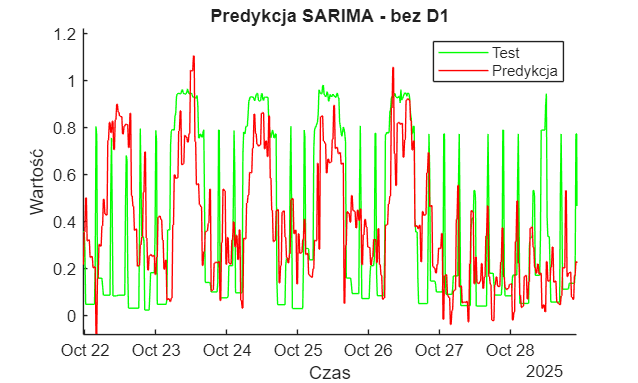



figure;
hold on;
plot(ab_diff_test.Time, ab_diff_test_norm, 'Color', 'green', 'DisplayName', 'Test');
plot(ab_diff_test.Time(1:length(final_prediction)), final_prediction, 'Color', 'red', 'DisplayName', 'Predykcja');
title('Predykcja SARIMA - bez D1');
legend;
xlabel('Czas');
ylabel('Wartość');
xlim([datetime(2025,9,17,0,2,25)...
      datetime(2025,9,23,23,18,39)])
ylim([-0.13 1.17])
zlim([-1.00 1.00])